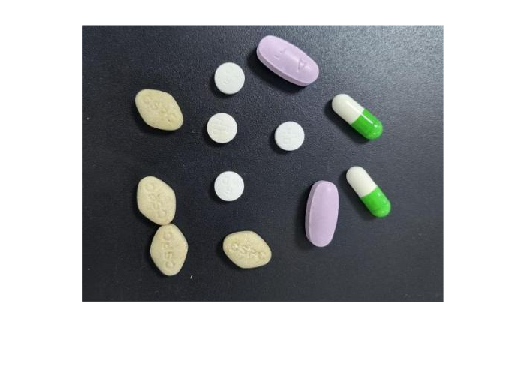

% 读取图像
A = imread("C:\Users\27492\Desktop\IMG\素材\图片1.png");
imshow(A);

使用matlab中自带的app——彩色分割器，将菱形黄色和椭圆紫色的药片识别出来

实验选择用ycbcr进行

%分割紫色药片
function [BW,maskedRGBImage] = createMask(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 07-May-2025
%------------------------------------------------------


% Convert RGB image to chosen color space
I = rgb2ycbcr(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 151.000;
channel1Max = 255.000;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 133.000;
channel2Max = 141.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 130.000;
channel3Max = 255.000;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end
 E=createMask(A);
 imshow(E);

用APP——图像区域分析器，处理多余的白色区域

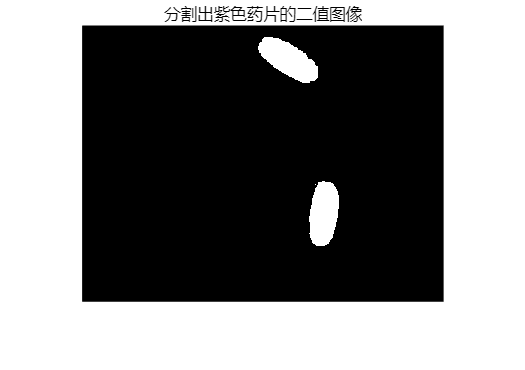

 function [BW_out,properties] = filterRegions(BW_in)
%filterRegions Filter BW image using auto-generated code from imageRegionAnalyzer app.

% Auto-generated by imageRegionAnalyzer app on 07-May-2025
%---------------------------------------------------------

BW_out = BW_in;

% Filter image based on image properties.
BW_out = bwpropfilt(BW_out,'Area',[2700, 2842]);

% Get properties.
properties = regionprops(BW_out, {'Area', 'Circularity', 'Eccentricity', 'EquivDiameter', 'EulerNumber', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Perimeter'});

end
E1=filterRegions(E);title("分割出紫色药片的二值图像")

用bwlabel计数

 [L,num]=bwlabel(E1);
 %输出对象数量
 disp(['紫色药片的数目',num2str(num)]);

紫色药片的数目2


同理，用相同的方法处理黄色的方形药片

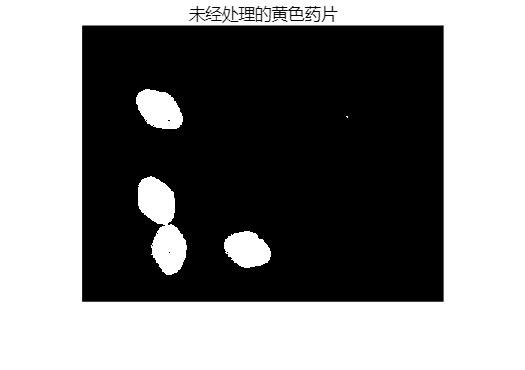

 %分割黄色方形药片采用hsv
 function [BW,maskedRGBImage] = createMask_1(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 07-May-2025
%------------------------------------------------------


% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.078;
channel1Max = 0.187;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.108;
channel2Max = 0.394;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.648;
channel3Max = 1.000;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end
Y=createMask_1(A);
imshow(Y);title("未经处理的黄色药片")

发现药片之间有粘连的情况，使用开运算

r1=10%调控结构元素se的半径

r1 = 10

% (通过调节此数值得出可以完整分割出圆形药片的方法
se1=strel('disk',r1)%生成圆形结构元素

se1 = strel 是具有以下属性的 disk 形结构元素:

      Neighborhood: [19×19 logical]
    Dimensionality: 2


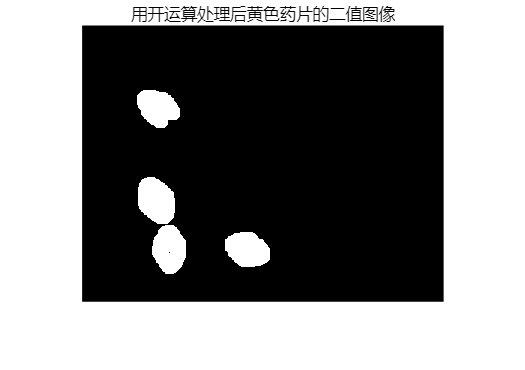

Y2=imopen(Y,se1);
imshow(Y2);title("用开运算处理后黄色药片的二值图像")

用bwlabel计数

 [L,num1]=bwlabel(Y2);
 %输出对象数量
 disp(['黄色方形药片的数目',num2str(num1)]);

黄色方形药片的数目4


运用app——彩色分割器，分割出胶囊和圆形白色药片

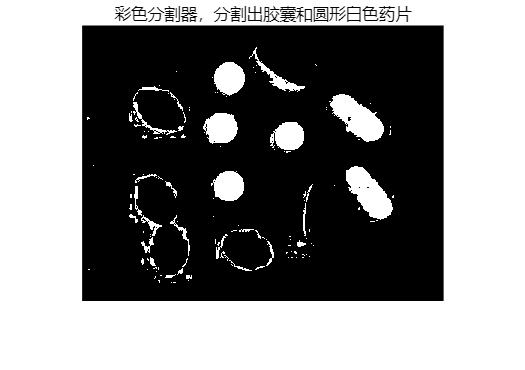

 function [BW,maskedRGBImage] = createMask_2(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 08-May-2025
%------------------------------------------------------


% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.428;
channel1Max = 0.173;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.076;
channel2Max = 0.350;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.045;
channel3Max = 1.000;

% Create mask based on chosen histogram thresholds
sliderBW = ( (I(:,:,1) >= channel1Min) | (I(:,:,1) <= channel1Max) ) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Invert mask
BW = ~BW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end
E3=createMask_2(A);
imshow(E3);title("彩色分割器，分割出胶囊和圆形白色药片")

使用开运算和闭运算去除多余部分

(即，先使用开运算腐蚀多余部分，再用闭运算还原）

r2=11%调控结构元素se的半径

r2 = 11

% (通过调节此数值得出可以完整分割出圆形药片的方法
se2=strel('disk',r2)%生成圆形结构元素

se2 = strel 是具有以下属性的 disk 形结构元素:

      Neighborhood: [21×21 logical]
    Dimensionality: 2


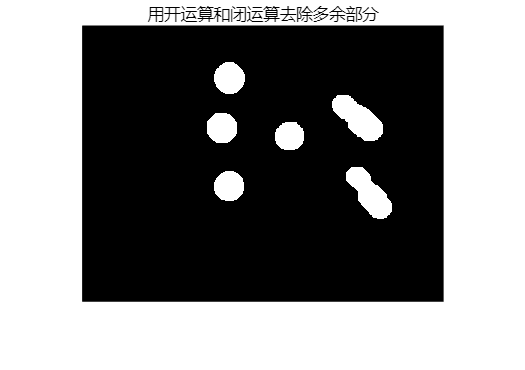

E4=imopen(E3,se2);
E5=imclose(E4,se2);
imshow(E5);title("用开运算和闭运算去除多余部分")

用APP——图像区域分析器，将胶囊提取出来

（胶囊与小药片面积存在明显不同，故使用面积筛选出）

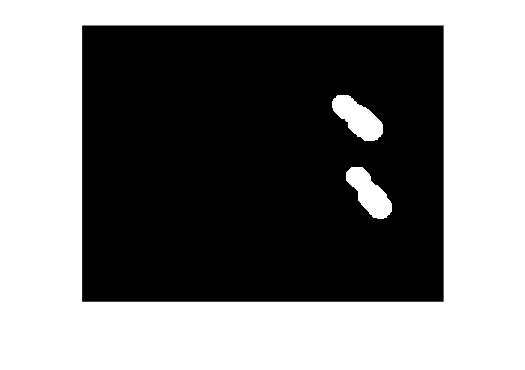

%筛选出胶囊
function [BW_out,properties] = filterRegions_1(BW_in)
%filterRegions Filter BW image using auto-generated code from imageRegionAnalyzer app.

% Auto-generated by imageRegionAnalyzer app on 08-May-2025
%---------------------------------------------------------

BW_out = BW_in;

% Filter image based on image properties.
BW_out = bwpropfilt(BW_out,'Area',[2000, 2374]);

% Get properties.
properties = regionprops(BW_out, {'Area', 'Circularity', 'Eccentricity', 'EquivDiameter', 'EulerNumber', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Perimeter'});
end
E6= filterRegions_1(E5);
imshow(E6);

用bwlabel计数

 [L,num2]=bwlabel(E6);
 %输出对象数量
 disp(['胶囊的数目为',num2str(num2)]);

胶囊的数目为2


用相同的方法计算出白色小药片的数目

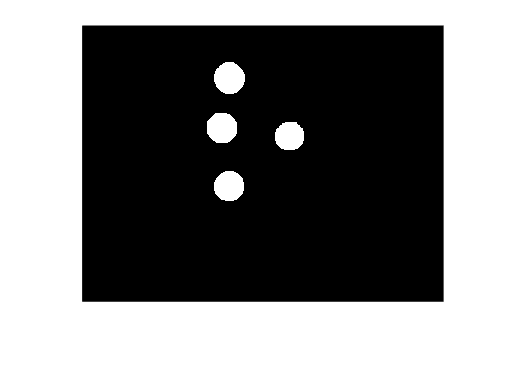

%筛选出白色小药片
 function [BW_out,properties] = filterRegions_2(BW_in)
%filterRegions Filter BW image using auto-generated code from imageRegionAnalyzer app.

% Auto-generated by imageRegionAnalyzer app on 08-May-2025
%---------------------------------------------------------

BW_out = BW_in;

% Filter image based on image properties.
BW_out = bwpropfilt(BW_out,'Area',[1205, 2000]);

% Get properties.
properties = regionprops(BW_out, {'Area', 'Circularity', 'Eccentricity', 'EquivDiameter', 'EulerNumber', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Perimeter'});
 end
E7 = filterRegions_2(E5);
imshow(E7);

%计数
[L,num3]=bwlabel(E7);
 %输出对象数量
 disp(['白色小药片的数目为',num2str(num3)]);

白色小药片的数目为4
